# Agent-based traffic signal management system by model-free reinforcement learning

- Author: Sherry Zhao

- Email: xiangxuezhao@gmail.com

- Last modified: 08/27/2020

## Overview:

Traffic congestion is always a daunting problem that affects people's daily life across the world. The objective of this work is to develop an intelligent traffic signal management to improve traffic performance, including alleviating traffic congestion, reducing waiting times, improving the throughput of a road network, and so on. Traditionally, traffic signal control typically formulates signal timing as an optimization problem. In this work, reinforcement learning (RL) techniques have been investigated to tackle traffic signal control problems through trial-and-error interaction with the environment. Comparing with traditional approaches, RL techniques relax the assumption about the traffic and do not necessitate creating a traffic model. Instead, it is a more human-based approach that can learn through trial-and-error search. The results from this work demonstrate the convergence and generalization performance of the RL approach as well as a significant improvement in terms of less waiting time, higher speed, collision avoidance, and higher throughput.

This LiveEdit script will demonstrate the workflow of designing and implementing a reinforcement learning algorithm to solve the intersection management problem.

## **Application Workflow**

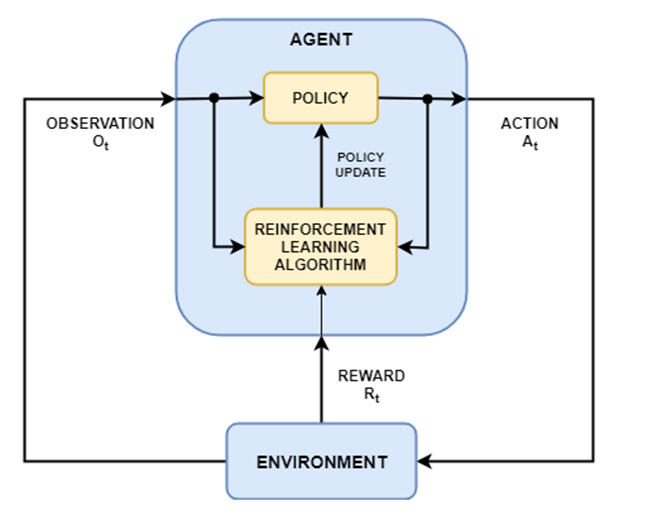

- Step 1: create an environment interface from MARTO specialized traffic simulator ([OpenTrafficLab](https://insidelabs-git.mathworks.com/marto/selfish-driving-cars/dsd-traffic-simulator)). 

- Step 2: specify traffic problem formulation, including observation space, traffic signal phase design (action), and reward function. 

- Step 3: create deep Q network agent. A list of other agent options can be found [here](https://www.mathworks.com/help/reinforcement-learning/agents.html?s_tid=CRUX_lftnav).

- Step 4: specify training options and train the agent.

- Step 5: validate the performance of the trained agent.

% add traffic simulator: OpenTrafficLab to path
folderName = fullfile(cd, 'OpenTrafficLab');
addpath(folderName)

### Step 1: create traffic simulator environment 

Create a MATLAB environment interface from MARTO specialized traffic simulator. For more information on the traffic simulator, see [OpenTrafficLab](https://insidelabs-git.mathworks.com/marto/selfish-driving-cars/dsd-traffic-simulator.git). For more information on defining a custom environment, see [create custom MATLAB environment template](https://www.mathworks.com/help/reinforcement-learning/ug/create-custom-matlab-environment-from-template.html).

% create RL environment from Matlab template
env = DrivingScenarioEnv;

### Step 2: specify traffic problem formulation

The problem formulation includes designing of traffic signal phase (**action space**), **observation space**, and **reward function**.

**Action space: **

Three different designs of traffic signal phases have been created as demonstrated in the figures below. In each of the design, the traffic signal phases in total are showed, where each of the signal phases corresponding to the right-of-way (i.e. green light) time interval assigned to a set of non-conflicting vehicular movement at the intersection. In the context of fixed time traffic signal control, the signal phases are changed sequentially in a pre-defined manner. Here, for the agent-based traffic signal management system, phased are decided by RL agent according to the real-time traffic conditions.

Design 1:

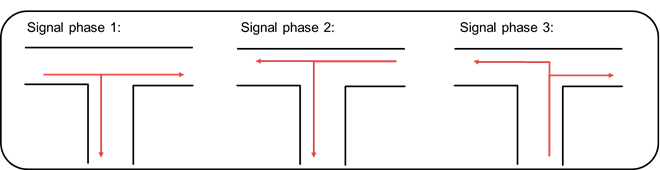

Design 2:

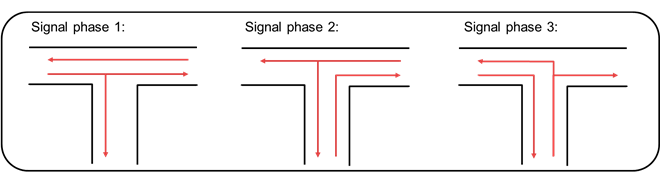

Design 3:

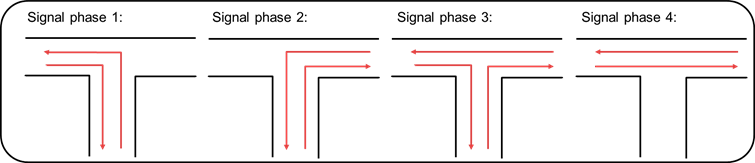

The user can specify which traffic signal design to be implemented by changing the env.TrafficSignalDesign. Also, the users can test their own signal phase design by creating their own signalPhaseDesign.m function.

% specific action space
env.TrafficSignalDesign = 1; % or 2, 3
% As shown in the figure above, the dimension of signal phase is R^3 for design 1 and 2, R^4 for design 3
SignalPhaseDim = 3;

Then, the action for the RL agent is to decide which signal phase to be based on real-time traffic information. The parameters associated with the action is the duration of each signal phase, whether we want to have clearing phase (yellow time) between two signal phase, and how long would the clearing phase be.

- phaseDuration: the number of time steps for each signal phase to be

- clearingPhase: whether to have a clearing phase (or yellow light) after switching signal phase

- clearingPhaseTime: how long would the clearing phase to be

% specifiy environment properties
env.phaseDuration = 50;
env.clearingPhase = true;
env.clearingPhaseTime = 5;

**Observation space:**

Two observation spaces are created according to different traffic signal phase designs. Comparing with traffic signal design 1, where only cars from one of the roads are given with green light, traffic signal phase design 2 and 3 allow cars from multiple roads to pass. Thus, it is important to include the cars' intention (turn left or right) in the observation space. 

The observation space and traffic signal design correspond in the following ways. Specify the observation space based on your choice of traffic signal phase design.

- Traffic Signal Design 1 <----> Observation space 1 (**Dimension 10**) 

            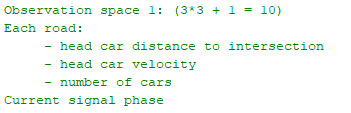

- Traffic Signal Design 2, and 3 <----> Observation space 2 (**Dimension 13**)

            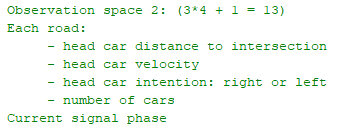

% specific observation space
env.ObservationSpaceDesign = 1; % or 2

Note: it is important to change the dimension of observations in the DrivingScenarioEnv accordingly !!!

**Reward:**

Specify the parameters for reward. The reward is weighted sum of a list of components, including penalty for waiting time, penalty for frequent signal phase change, penalty for car collision, reward for car pass the intersection (maximize throughput), and reward for higher passing speed.

% The car's speed below the threshold will be treated as waiting at the
% intersection
slowSpeedThreshold = 3.5;
% Add penalty for frequent/unnecessary signal phase switch
penaltyForFreqSwitch = 1;
% parameter for car collision
env.hitPenalty = 20;
env.safeDistance = 2.25;
% reward for car pass the intersection
env.rewardForPass = 10;

Obtain the observation and action information from the environment interface.

% obtain observation and action info
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);

### Step 3: create Deep Q Network (DQN) agent 

The deep Q-network (DQN) algorithm is a model-free, online, off-policy reinforcement learning method. A DQN agent is a value-based reinforcement learning agent that trains a critic to estimate the return or future rewards. DQN is a variant of Q-learning. For more information on Q-learning, see [Q-Learning Agents](https://www.mathworks.com/help/reinforcement-learning/ug/q-agents.html). For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

% policy representation by Neural Network
layers = [
    imageInputLayer([obsInfo.Dimension(1) 1 1],"Name","observations","Normalization","none")
    fullyConnectedLayer(256,"Name","obs_fc1")
    reluLayer("Name","obs_relu1")
    fullyConnectedLayer(256,"Name","obs_fc2")
    reluLayer("Name","obs_relu2")
    fullyConnectedLayer(SignalPhaseDim,"Name","Q")
    ];
lgraph = layerGraph(layers);

figure
plot(lgraph)

% critic options
criticOpts = rlRepresentationOptions('LearnRate',5e-03,'GradientThreshold',1);
criticOpts.Optimizer = 'sgdm';
criticOpts.UseDevice = 'cpu';
% create critic function
critic = rlQValueRepresentation(lgraph,obsInfo,actInfo,...
    'Observation',{'observations'},criticOpts);

To create the DQN agent, first specify the DQN agent options using [rlDQNAgentOptions](https://www.mathworks.com/help/reinforcement-learning/ref/rldqnagentoptions.html).

% agent options
agentOpts = rlDQNAgentOptions;
agentOpts.EpsilonGreedyExploration.EpsilonDecay = 1e-4;
agentOpts.DiscountFactor = 0.99;
agentOpts.TargetUpdateFrequency = 1; 

Then create the agent using the specified critic representation and agent options. For more information, see [`rlDQNAgent`](https://www.mathworks.com/help/reinforcement-learning/ref/rldqnagent.html).

% create agent
agent = rlDQNAgent(critic, agentOpts);

### Step 4: train agent 

To train the agent using parallel computing, specify the following training options. For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

% specify training option
trainOpts = rlTrainingOptions;

trainOpts.MaxEpisodes                = 2000;
trainOpts.MaxStepsPerEpisode         = 1000;
trainOpts.StopTrainingCriteria       = "AverageReward";
trainOpts.StopTrainingValue          = 550;
trainOpts.ScoreAveragingWindowLength = 5;

trainOpts.SaveAgentCriteria  = "EpisodeReward";
trainOpts.SaveAgentValue     = 800;
trainOpts.SaveAgentDirectory = "savedAgents";

trainOpts.UseParallel = false;
trainOpts.ParallelizationOptions.Mode = "async";
trainOpts.ParallelizationOptions.DataToSendFromWorkers = "experiences";
trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 30;
trainOpts.ParallelizationOptions.WorkerRandomSeeds = -1;

trainOpts.Verbose = false;
trainOpts.Plots = "training-progress";

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training the agent is a computationally intensive process that takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`. Due to randomness in the asynchronous parallel training, you can expect different training results from the following training plot. The plot shows the result of training with six workers.

doTraining = false;

if doTraining    
    % Train the agent.
    trainingInfo = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    folderName = cd; % change current folder
    folderName = fullfile(folderName, 'savedAgents');
    filename = strcat('TjunctionDQNAgentDesign', num2str(env.TrafficSignalDesign), '.mat');
    file = fullfile(folderName, filename);
    load(file);
end

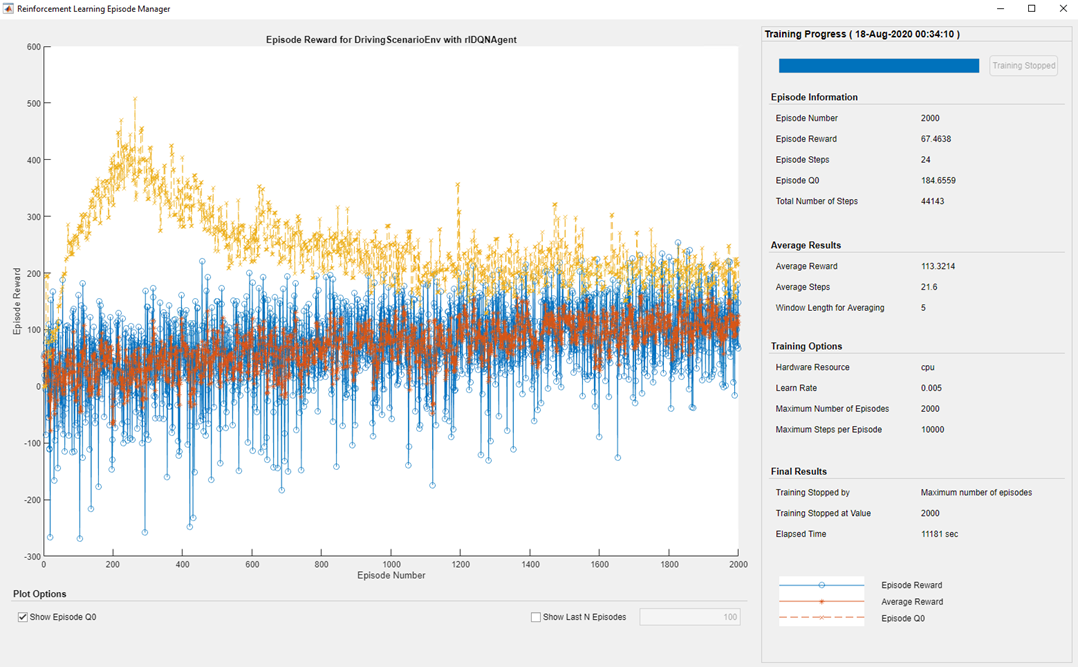

### Step 5: simulate agent

simOpts = rlSimulationOptions('MaxSteps',1000);
experience = sim(env,agent,simOpts);
totalReward = sum(experience.Reward);

*Copyright 2020 The MathWorks, Inc.*